% 清空
clc;
clear;

% data path
data_path = 'D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared';
% saving path
save_path = ['D:\Matlab_data_file\EEGdata\var',filesep];

save_path = 'D:\Matlab_data_file\EEGdata\erp\'

% 将每个被试平均后的数据合成一个数据集
for i = 1:4
    try
        % 拼接被试的文件名
        data_name = ['sub',num2str(i),'.set'];
        % 导入该被试数据
        EEG = pop_loadset('filename',data_name,'filepath',data_path);
        % 检查EEG数据是否完好
        EEG = eeg_checkset(EEG);
        
        % EEG.data是三维数据集：channel × timepoint × trial
        % 做trial水平上的平均，然后清除trial维度
        % 将第i个被试的数据（二维数据，channel×timepoint）放入三维数据集EEG_avg(i,:,:)中
        % EEG_avg是一个三维数据集：subject × channel × timepoint
        EEG_avg(i,:,:) = squeeze(mean(EEG.data,3));
    catch ME
    end
end

pop_loadset(): loading file D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared\sub1.set ...
eeg_checkset: recomputing the ICA activation matrix ...
pop_loadset(): loading file D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared\sub2.set ...
eeg_checkset: recomputing the ICA activation matrix ...
pop_loadset(): loading file D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared\sub3.set ...
eeg_checkset: recomputing the ICA activation matrix ...
pop_loadset(): loading file D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared\sub4.set ...
eeg_checkset: recomputing the ICA activation matrix ...


% 把EEG_avg变量保存成group_level_erp.mat
save([save_path,'group_lv_erp.mat'],"EEG_avg");

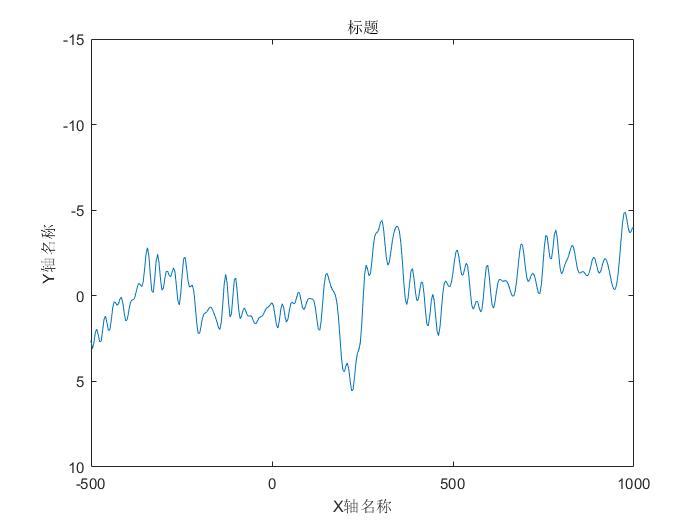

% 绘制组水平的erp曲线
% 可以在EEG.chanlocs中寻找特定电极的索引值，然后提取特定的通道
% 这里以索引值为5的电极点为例(AF4)
COI = 5;

% 生成一个空画布
figure;
% 提取所有被试的COI位置上的电极点数据，此时数据变成subject × 1 × timepoint数组
% 对第一个维度（被试维度）做平均，此时数据变量1 × 1 × timepoint数组
% 挤压多余维度，使数据变成只有timepoint的一维数组
mean_data= squeeze(mean(EEG_avg(:,COI,:),1));
plot(EEG.times,mean_data);

%reverse the direction of the Y axis
set(gca,'YDir','reverse');

% define the region to display
axis([-500 1000 -15 10]);

%各种图注
title('标题');
xlabel('X轴名称');
ylabel('Y轴名称');

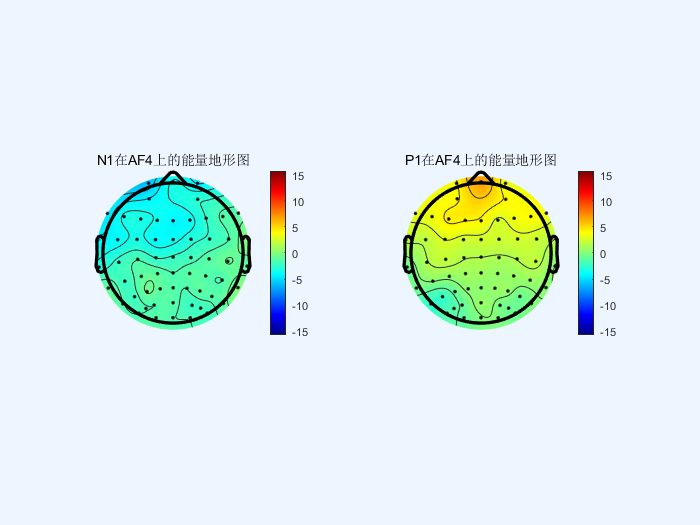

% 绘制组水平的地形图
% 通过erp曲线图确定感兴趣成分的峰值时间，并选择合适的半径作为计算区间
N1_peak = 280;
P1_peak = 200;

% 获取与上述时间区间相对应的索引
n_idx = time_intv_index(EEG,N1_peak,10);
p_idx = time_intv_index(EEG,P1_peak,10);

% EEG_avg是一个三维数据集，subject × channel × timepoint
% 提取所有被试，所有通道，感兴趣的时间区间内的数据
% 对这个时间区间内的所有数据进行平均，然后对所有被试进行平均，然后挤压多余的维度
% 得到的数据是在该时间区间内，内各个通道的每个被试平均的平均能量值
n_amplitude = squeeze(mean(mean(EEG_avg(:,:,n_idx),3),1));
p_amplitude = squeeze(mean(mean(EEG_avg(:,:,p_idx),3),1));

% 生成空白画布
figure;

% 一行二列第一张
subplot(1,2,1);
topoplot(n_amplitude,EEG.chanlocs,'maplimits',[-15,15]);
title('N1在AF4上的能量地形图');
colorbar;

% 一行二列第二张
subplot(1,2,2);
topoplot(p_amplitude,EEG.chanlocs,'maplimits',[-15,15]);
title('P1在AF4上的能量地形图');
colorbar;

function idx = time_intv_index(data,t_peak,len)% 计算时间点索引的函数
    t_min = t_peak - len;
    t_max = t_peak + len;
    idx = find(data.times>t_min & data.times<t_max);
end